## Load the Data and place into seperate containers

clear;
load exp2.mat 
time = exp2.X.Data;
vel_motor = exp2.Y(1).Data;
vel_table = exp2.Y(2).Data;
voltage = exp2.Y(3).Data;

## Filter Data

% Filter parameter
tau_lp = 1/(40*pi);
G_f = 1/(tau_lp+1);
vel_table = lowpass(vel_table, G_f);
vel_motor = lowpass(vel_motor, G_f);

## Plot for visualization

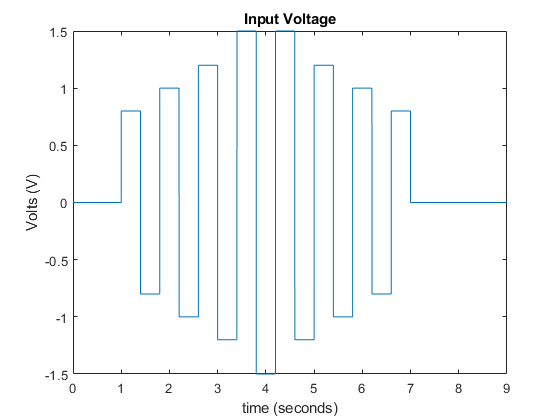

plot(time,voltage)
title('Input Voltage')
ylabel('Volts (V)')
xlabel('time (seconds)')

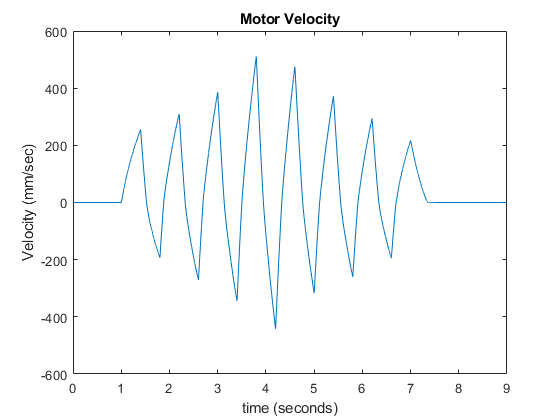


plot(time,vel_motor)
title('Motor Velocity')
ylabel('Velocity (mm/sec)')
xlabel('time (seconds)')

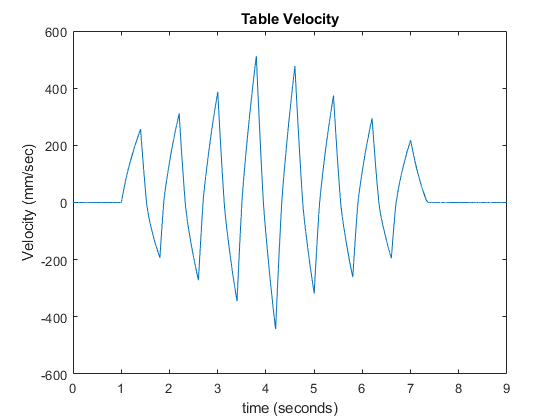


plot(time,vel_table)
title('Table Velocity')
ylabel('Velocity (mm/sec)')
xlabel('time (seconds)')

## Calculate Accelerations Numerically

acc_motor = diff(vel_motor);
time_acc = time(1:numel(acc_motor))

time_acc =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


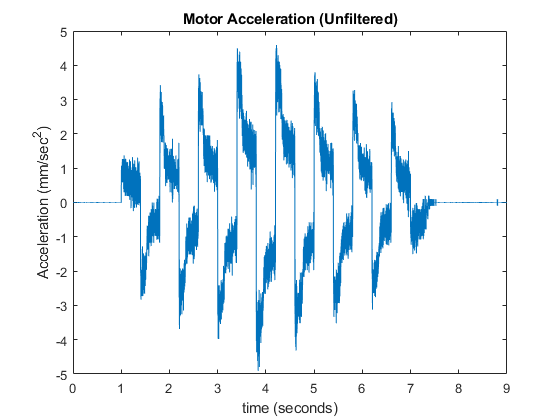

plot(time_acc,acc_motor)
title('Motor Acceleration (Unfiltered)')
ylabel('Acceleration (mm/sec^2)')
xlabel('time (seconds)')

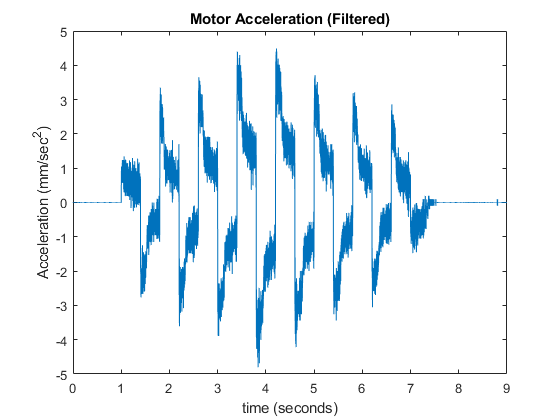


% Filter
y = lowpass(acc_motor, G_f);
plot(time_acc,y)
title('Motor Acceleration (Filtered)')
ylabel('Acceleration (mm/sec^2)')
xlabel('time (seconds)')